# ECEN 611 Homework 4: Gap Function and Mutual Inductance for Salient Pole Rotor 

`Shuxuan Chen | 132006082 | Fall 2024`

*Last updated: Oct  12*

clearvars 
clc 

## Problem 1 

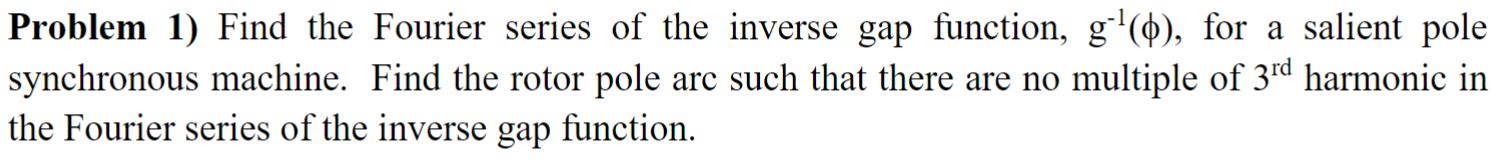

Express gap length as a function of the angle Φ and θr.

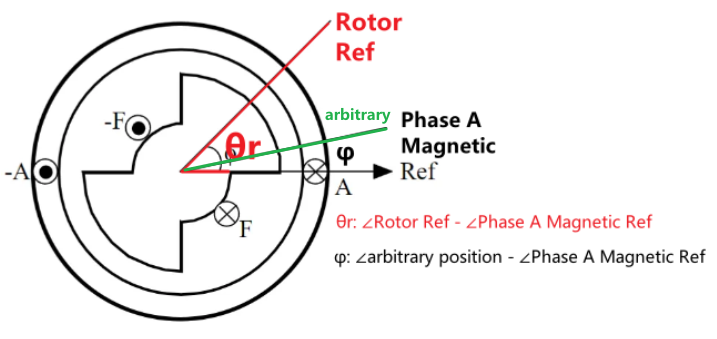

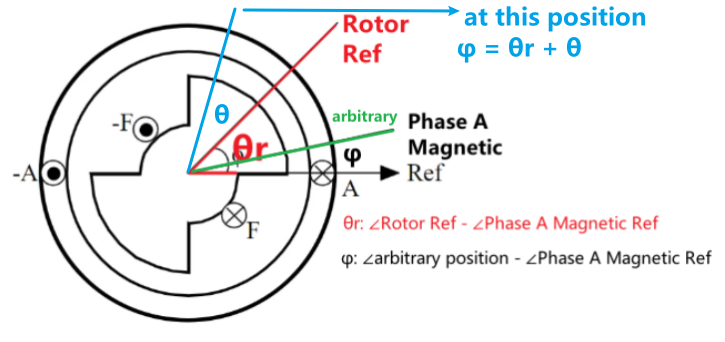

syms g_min g_max     positive real
syms alpha           positive real 
syms phi                      real 
syms theta_r theta            real
syms N_s N_r
syms g_phi(phi)

assume( (alpha > 0) & (alpha <= deg2rad(180)) )
assume( (theta_r >= 0) & (theta_r <= deg2rad(360)) )

% assume(phi > 0)

digits(4)

T = 2*pi;
POLEARC = deg2rad(90);
THETA_R = deg2rad(45);
NS = 1;
NR = 1;

% alpha is pole arc 
% beta is the non-pole arc 
poleArc = alpha;
midArc = (deg2rad(360) - 2*poleArc) / 2; 

vars = [poleArc g_min g_max theta_r N_s N_r];
VALS = [POLEARC 0.5   0.8   THETA_R NS  NR];

### Original Gap Function g(φ) where φ ∈ [0, T]

% Starting at phi = 0

phiRotorShape = [-poleArc/2 poleArc/2 midArc poleArc midArc poleArc/2] % 'absolute value': non-dependent on reference 

$$phiRotorShape = \left(\begin{array}{cccccc} -\frac{\alpha }{2} & \frac{\alpha }{2} & \pi -\alpha & \alpha & \pi -\alpha & \frac{\alpha }{2} \end{array}\right)$$

% the idea of "close the loop" manifests here as well 

% -poleArc/2 and poleArc/2 <-- my treatment that sets -poleArc/2 rather 0 for the first angle is awesome! 
% Making phi starts at 0°, this treatment has no less meaning that 2's Complement in computer history

phiRotorShapeCumSum = cumsum(phiRotorShape) + theta_r % dependency on rotor position 

$$phiRotorShapeCumSum = \left(\begin{array}{cccccc} \theta_{r}-\frac{\alpha }{2} & \theta_{r} & \theta_{r}-\alpha +\pi & \theta_{r}+\pi & \theta_{r}-\alpha +2\,\pi & \theta_{r}-\frac{\alpha }{2}+2\,\pi \end{array}\right)$$

% phi is defined as the angle 
%
% between 
%
% the lower boundary of the rotor pole 
%
% and
%
% the phase A magnetic reference

% When the rotor starts spinning, there will be an angle between 
% the lower boundary of the rotor pole and the phase A magnetic reference
% to account for this effect, simply replace phi with (phi + theta_r)

% this showcases the importance of having a universal, static reference

gap = [g_min, g_max, g_min, g_max, g_min];

firstPhi = phiRotorShapeCumSum(1);
secondPhi = phiRotorShapeCumSum(2);
firstGap = gap(1);

g_phi(phi) = piecewise(firstPhi <= phi <= secondPhi, firstGap)

$$g\_phi(phi) = \left\{ \begin{array}{cl} g_{\min} & \text{ if }\varphi \leq \theta_{r}\wedge 2\,\theta_{r}\leq \alpha +2\,\varphi \end{array}\right.$$

% g_theta(theta) = piecewise( ...
%     theta_r <= theta < theta_r + poleArc/2, g_min, ...
%     theta_r + poleArc/2 <= theta < theta_r + poleArc/2 + midArc, g_max, ...
%     theta_r + poleArc/2 + midArc <= theta < theta_r + poleArc/2 + midArc + poleArc, g_min, ...
%     theta_r + poleArc/2 + midArc + poleArc <= theta <= theta_r + poleArc/2 + midArc + poleArc + midArc, g_max, ...
%     theta_r + poleArc/2 + midArc + poleArc + midArc <= theta_r <= theta_r + poleArc/2 + midArc + poleArc + poleArc/2, g_min ... 
% )

for k = 2:length(phiRotorShapeCumSum)-1

    thisPhi = phiRotorShapeCumSum(k);
    nextPhi = phiRotorShapeCumSum(k+1); 
    thisGap = gap(k);

    g_phi(phi) = piecewise( ...
        thisPhi <= phi <= nextPhi, thisGap, ...
        phi <= thisPhi, g_phi(phi) ...
    ); 
end 

disp(g_phi(phi))

$$\left\{ \begin{array}{cl} g_{\min} & \text{ if }\theta_{r}+2\,\pi \leq \alpha +\varphi \wedge \frac{\alpha }{2}+\varphi \leq \theta_{r}+2\,\pi \\ g_{\max} & \text{ if }\alpha +\varphi \leq \theta_{r}+2\,\pi \wedge \theta_{r}+\pi \leq \varphi \\ g_{\min} & \text{ if }\alpha +\varphi \leq \theta_{r}+2\,\pi \wedge \theta_{r}+\pi \leq \alpha +\varphi \wedge \varphi \leq \theta_{r}+\pi \\ g_{\max} & \text{ if }\theta_{r}\leq \varphi \wedge \varphi \in \mathbb{R}\wedge \alpha +\varphi \leq \theta_{r}+\pi \\ g_{\min} & \text{ if }\varphi \leq \theta_{r}\wedge \varphi \in \mathbb{R}\wedge 2\,\theta_{r}\leq \alpha +2\,\varphi \end{array}\right.$$

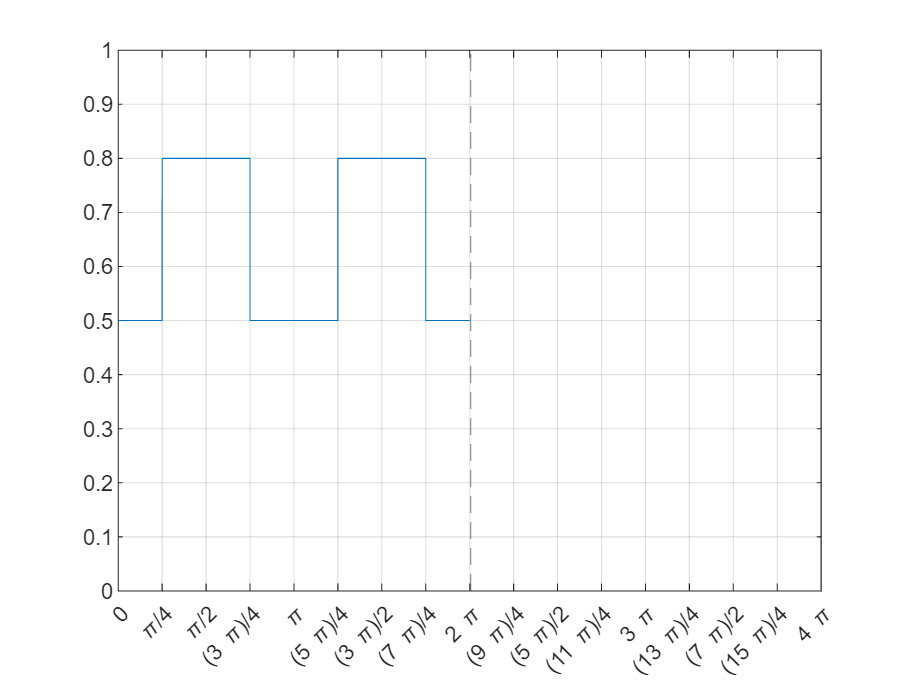

% When we are focusing on the gap function only
% for simplicity we will assume the rotor is not spinning 
% so that the function's dependency on theta_r is removed

% therefore, an arbitrary θr is selected, which is 0° according to the
% position shown in the figure  

figure 
fplot(subs(g_phi, vars, VALS), [0 2*T])
hold on 
ylim([0 1])
grid on 
ax = gca;
S = sym(ax.XLim(1):pi/4:ax.XLim(2));
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);

### Original Inverse Gap Function g(φ)^(-1) where φ ∈ [0, T]

g_phi_inv = 1/g_phi

$$g\_phi\_inv(phi) = \left\{ \begin{array}{cl} \frac{1}{g_{\min}} & \text{ if }\theta_{r}+2\,\pi \leq \alpha +\varphi \wedge \frac{\alpha }{2}+\varphi \leq \theta_{r}+2\,\pi \\ \frac{1}{g_{\max}} & \text{ if }\alpha +\varphi \leq \theta_{r}+2\,\pi \wedge \theta_{r}+\pi \leq \varphi \\ \frac{1}{g_{\min}} & \text{ if }\alpha +\varphi \leq \theta_{r}+2\,\pi \wedge \theta_{r}+\pi \leq \alpha +\varphi \wedge \varphi \leq \theta_{r}+\pi \\ \frac{1}{g_{\max}} & \text{ if }\theta_{r}\leq \varphi \wedge \varphi \in \mathbb{R}\wedge \alpha +\varphi \leq \theta_{r}+\pi \\ \frac{1}{g_{\min}} & \text{ if }\varphi \leq \theta_{r}\wedge \varphi \in \mathbb{R}\wedge 2\,\theta_{r}\leq \alpha +2\,\varphi \end{array}\right.$$

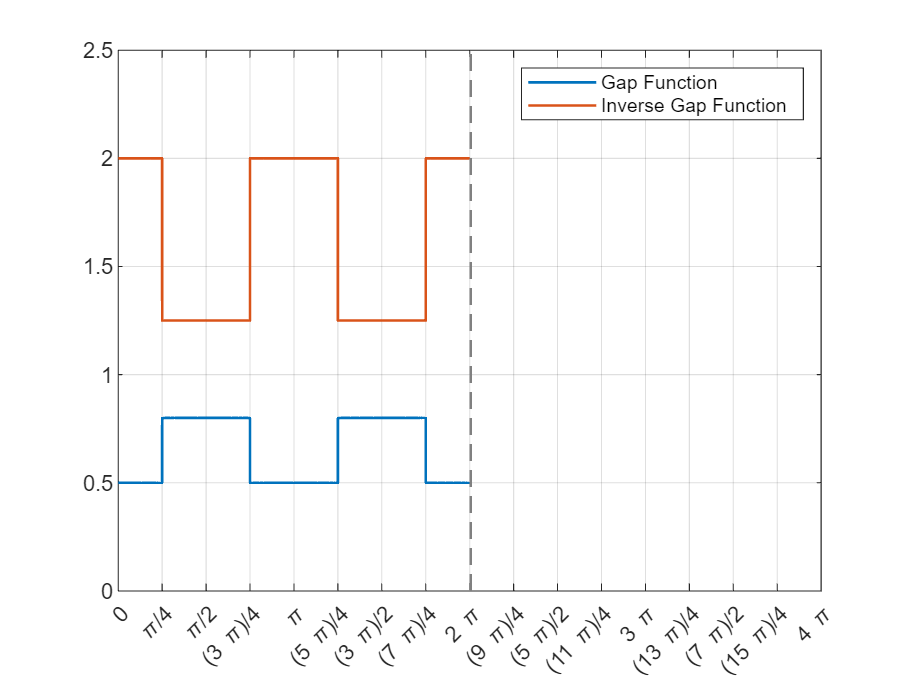

figure 
fplot(subs(g_phi, vars, VALS), [0 2*T], ...
    "DisplayName", "Gap Function", ...
    "LineWidth", 1.2)
hold on 
fplot(subs(g_phi_inv, vars, VALS), [0 2*T], ...
    "DisplayName", "Inverse Gap Function", ...
    "LineWidth", 1.2)
hold off 
ylim([0 2.5])
grid on 
legend 

ax = gca;
S = sym(ax.XLim(1):pi/4:ax.XLim(2));
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);

### Extended Inverse Gap Function g(φ)^(-1) where φ ∈ [-2T, 2T]

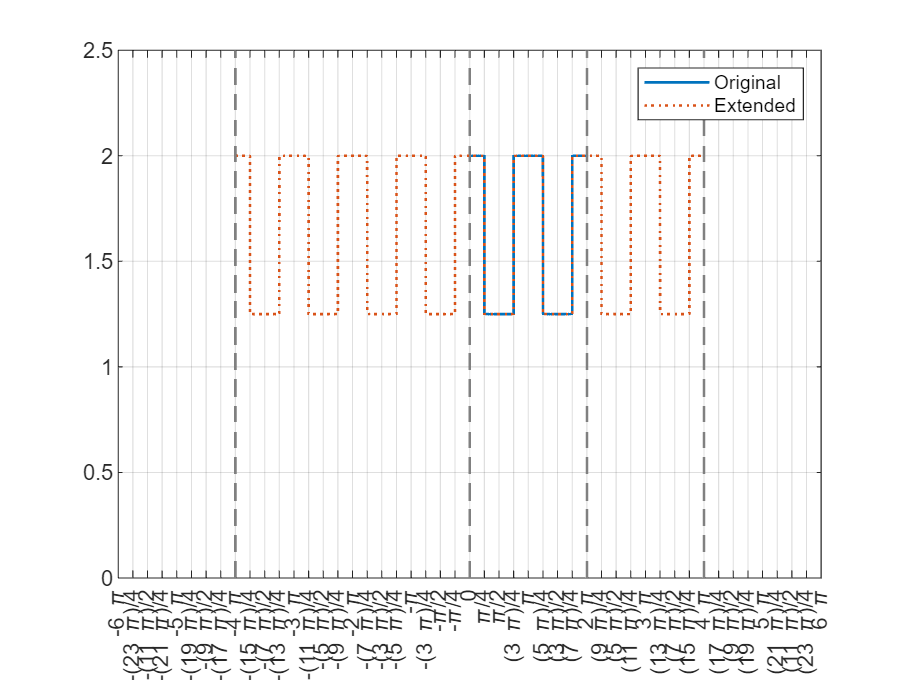

g_phi_inv_ext(phi) = piecewise( ...
    -2*T <= phi < -T, g_phi_inv(phi+2*T), ...
    -T <= phi < 0, g_phi_inv(phi+T), ...
    0 <= phi < T, g_phi_inv(phi), ...
    T <= phi < 2*T, g_phi_inv(phi-T) ...
);

figure 
fplot(subs(g_phi_inv, vars, VALS), [-3*T 3*T], ...
      "DisplayName", "Original", ...
      "LineWidth", 1.2)
hold on
fplot(subs(g_phi_inv_ext, vars, VALS), [-3*T 3*T], ...
      "DisplayName", "Extended", ...
      "LineStyle",":", ...
      "LineWidth", 1.2 ...
      )
hold off 
ylim([0 2.5])
grid on 
legend 
ax = gca;
S = sym(ax.XLim(1):pi/4:ax.XLim(2));
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);

% g_phi_temp(phi) = subs(g_phi_inv_ext, vars, VALS)
% 
% g_phi_temp(pi)
% g_phi_temp(3*pi)
% g_phi_temp(-pi/2)
% 
% g_phi_temp(phi)-g_phi_temp(-phi)
% 
% isequal(g_phi_temp(phi)-g_phi_temp(-phi),0)

### (No Longer Needed) Shifted (Even) Inverse Gap Function g(φ)^(-1) where φ ∈ [-2T, 2T]

Because of 

`phiRotorShape = [-poleArc/2 poleArc/2 midArc poleArc midArc poleArc/2],`

the `g_phi_inv_ext` is already an even function. Therefore, shifting is no longer needed.

% phiRotorShape = [-poleArc/2 poleArc/2 midArc poleArc midArc poleArc/2] % 'absolute value': non-dependent on reference

% shiftedAngle = poleArc/2; 
% g_phi_inv_even(phi) = simplify(g_phi_inv_ext(phi+shiftedAngle))
% 
% figure 
% fplot(subs(g_phi_inv_ext, vars, VALS), [-3*T 3*T], ...
%       "DisplayName", "Unshifted", ...
%       "LineWidth", 1.2)
% hold on 
% fplot(subs(g_phi_inv_even, vars, VALS), [-3*T 3*T], ...
%       "DisplayName", "Even", ...
%       "LineStyle",":", ...
%       "LineWidth", 1.2 ...
%       )
% hold off 
% ylim([0 2.5])
% grid on 
% legend 

g_phi_inv(phi)

$$ans = \left\{ \begin{array}{cl} \frac{1}{g_{\min}} & \text{ if }\theta_{r}+2\,\pi \leq \alpha +\varphi \wedge \frac{\alpha }{2}+\varphi \leq \theta_{r}+2\,\pi \\ \frac{1}{g_{\max}} & \text{ if }\alpha +\varphi \leq \theta_{r}+2\,\pi \wedge \theta_{r}+\pi \leq \varphi \\ \frac{1}{g_{\min}} & \text{ if }\alpha +\varphi \leq \theta_{r}+2\,\pi \wedge \theta_{r}+\pi \leq \alpha +\varphi \wedge \varphi \leq \theta_{r}+\pi \\ \frac{1}{g_{\max}} & \text{ if }\theta_{r}\leq \varphi \wedge \varphi \in \mathbb{R}\wedge \alpha +\varphi \leq \theta_{r}+\pi \\ \frac{1}{g_{\min}} & \text{ if }\varphi \leq \theta_{r}\wedge \varphi \in \mathbb{R}\wedge 2\,\theta_{r}\leq \alpha +2\,\varphi \end{array}\right.$$

### Fourier Series of Shifted (Even) Inverse Gap Function g(φ)^(-1) where φ ∈ [0, T]

digits(4)

syms n positive integer

% a0 = vpa( (1/T) * int( subs(g_phi_inv_even, theta_r, THETA_R), phi, [0 T]) )
% an = (2/T) * int( subs(g_phi_inv_even, theta_r, THETA_R) * cos(n * phi), phi, 0, T);
% bn = (2/T) * int( subs(g_phi_inv_even, theta_r, THETA_R) * sin(n * phi), phi, 0, T);

a0 = vpa( (1/T) * int( subs(g_phi_inv, theta_r, THETA_R), phi, [0 T], 'IgnoreSpecialCases', true) )

$$a0 = \left\{ \begin{array}{cl} \frac{0.5}{g_{\min}}+\frac{0.5}{g_{\max}} & \text{ if }\alpha =1.571\\ \frac{0.2387\,\alpha }{g_{\min}}-\frac{0.1592\,\left(\alpha -3.142\right)}{g_{\max}}+\frac{0.375}{g_{\max}} & \text{ if }\alpha \leq 0.7854\\ \frac{0.2387\,\alpha }{g_{\min}}-\frac{0.3183\,\left(\alpha -3.142\right)}{g_{\max}}+\frac{0.125}{g_{\min}} & \text{ if }1.571\leq \alpha \\ \frac{0.1592\,\left(\alpha -0.7854\right)}{g_{\min}}-\frac{0.3183\,\left(\alpha -3.142\right)}{g_{\max}}+\frac{0.2387\,\alpha }{g_{\min}} & \text{ if }\alpha \in \left(0.7854,1.571\right] \end{array}\right.$$

an = (2/T) * int( subs(g_phi_inv, theta_r, THETA_R) * cos(n * phi), phi, [0 T]);

bn = (2/T) * int( subs(g_phi_inv, theta_r, THETA_R) * sin(n * phi), phi, [0 T]);

orderOfHarmonics = 1:13;
an_13 = vpa( simplify(subs(an, n, orderOfHarmonics))) 

bn_13 = vpa( simplify(subs(bn, n, orderOfHarmonics)) )


g_phi_inv_even_fourier = a0 + ...
                    sum( an_13 .* cos(orderOfHarmonics .* phi) + ...
                         bn_13 .* sin(orderOfHarmonics .* phi) )

figure 
fplot(subs(g_phi_inv_even, vars, VALS), [0 T], ...
      "DisplayName", "Even Inverse Gap Function", ...
      "LineWidth", 1.2)

Unrecognized function or variable 'g_phi_inv_even'.

hold on 
fplot(subs(g_phi_inv_even_fourier, vars, VALS), [0 T], ...
      "DisplayName", "Fourier Series", ...
      "LineStyle",":", ...
      "LineWidth", 1.2 ...
      )
hold off 
ylim([0 2.5])
grid on 
legend 

### Removal of Multiples of 3rd Harmonics in Fourier Series of Shifted (Even) Inverse Gap Function g(φ)^(-1) where φ ∈ [0, T]

terms = children(g_phi_inv_even_fourier);
multiplesOf3rd = find(mod(orderOfHarmonics,3)==0)

% Initialize a symbolic zero to accumulate matching terms
matching_terms = [];

for i = 1:length(terms)
    if has(terms{i}, cos(multiplesOf3rd*phi))
        matching_terms = [matching_terms terms{i}]; % Accumulate matching terms
    end
end

disp(matching_terms);

It is clear that when $\alpha =\frac{\pi }{3}$, both cos(6*phi) and cos(12*phi) are eliminated as both sin(3*alpha) and sin(6*alpha) are zero.

## Problem 2 

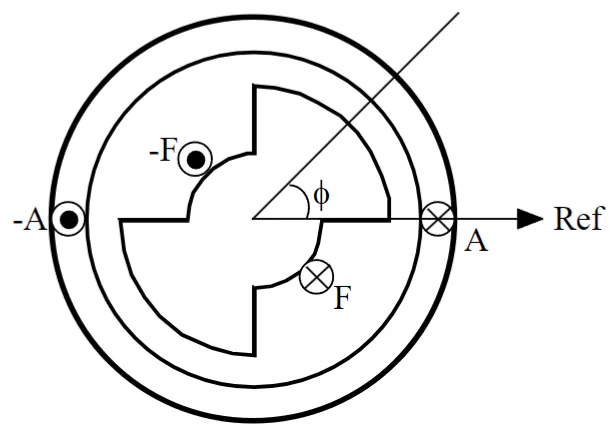

*For finding the magnetizing inductance you need to find the winding function of the stator winding, then the inverse airgap function and then follow the approach in the book to find the magnetizing of the stator winding which in this case due to saliency on the rotor it will be varying with rotor position like what is shown in the book.*

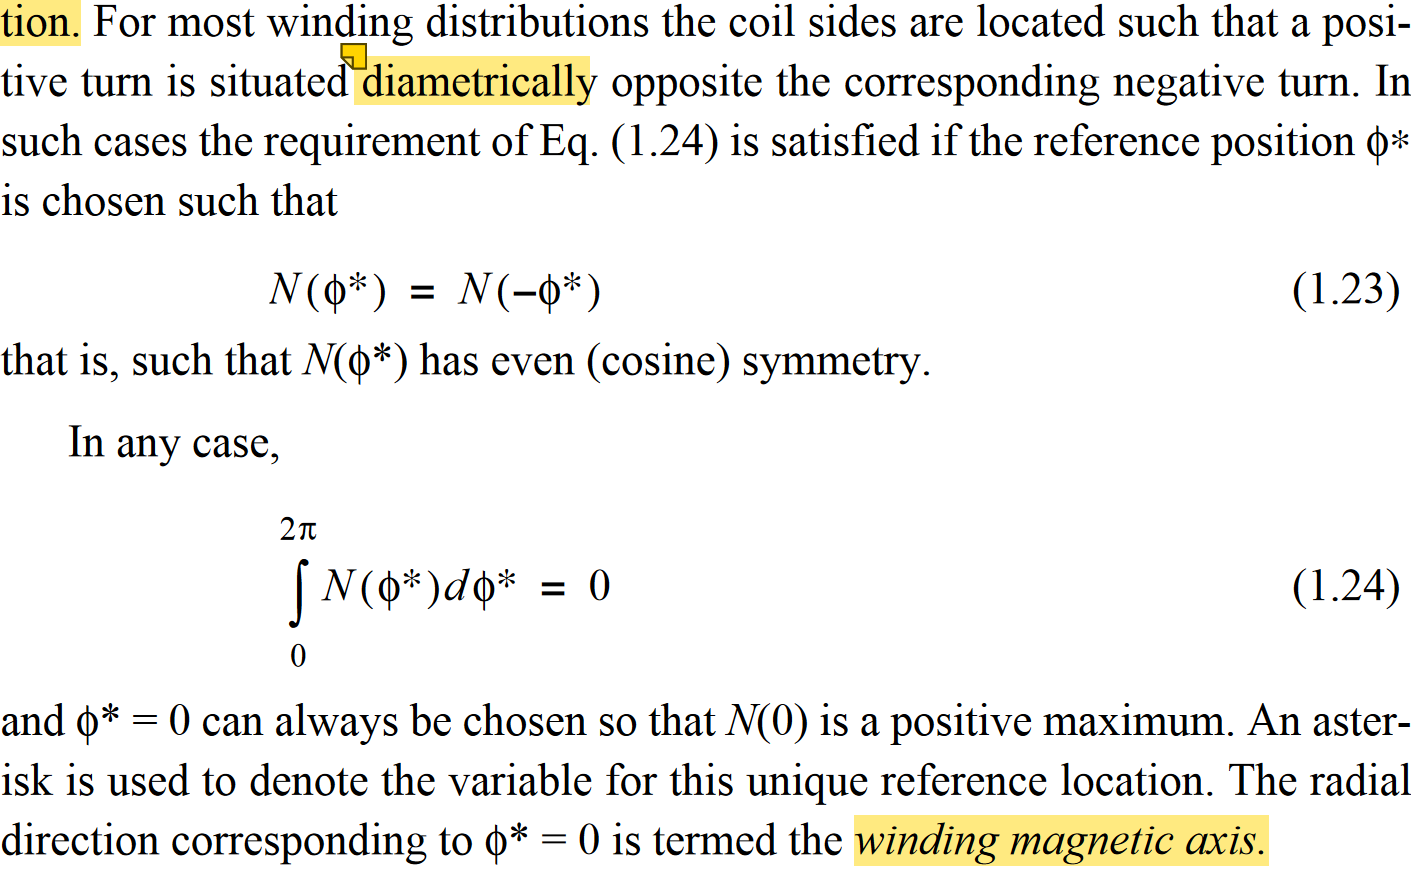

### **Original Stator Counting Function n(φ) where φ ∈ [0, T]**

numberOfConductors = 2; 

syms I positive real 
syms N_s 

NS = 1;
% close the "loop": one turn is at phi=0 and the other T/2
% however, closing the "loop" by winding up to T (same as phi=0) makes
% programming easier because that corresponds to a full period 
turnsStatorNum = [1 -1 1] * N_s;   % number of turns at each location: replace Nt with 1 for simplicity  
turnsStatorPhi = [0 T/2 T];  % angle of each location 

% Initialize the piecewise function with the first interval
phiReference = sym(0); % unique and universal "yardstick" for all angles associated with rotor and stator 

turnsStatorNumLevel = cumsum(turnsStatorNum)
% Initialize the piecewise function with the first interval
statorCountingFunction(phi) = turnsStatorNumLevel(1);

for k = 1:length(turnsStatorPhi)-1
    thisAngle = phiTurningPoint(k);
    nextPhi = phiTurningPoint(k+1);
    statorCountingFunction(phi) = piecewise(thisAngle <= phi < nextPhi, turnsStatorNumLevel(k), ...
                                            phiReference <= phi < thisAngle, statorCountingFunction);
end 
disp(statorCountingFunction(phi))

figure 
fplot(subs(statorCountingFunction(phi), N_s, NS), [-2*T 2*T], ...
    "DisplayName", "Counting Function", ...
    "LineWidth", 1.2)
ylim([-1 2])
grid on  
legend 

### **Extended Stator Counting Function n(φ) where φ ∈ [-2T, 2T]**

statorCountingFunction_ext(phi) = piecewise( ...
    -2*T <= phi < -T, statorCountingFunction(phi+2*T), ...
    -T <= phi < 0, statorCountingFunction(phi+T), ...
    0 <= phi < T, statorCountingFunction(phi), ...
    T <= phi < 2*T, statorCountingFunction(phi-T) ...
)

figure 
fplot(subs(statorCountingFunction(phi), N_s, NS), [-3*T 3*T], ...
    "DisplayName", "Original", ...
    "LineWidth", 1.2)
hold on 
fplot(subs(statorCountingFunction_ext(phi), N_s, NS), [-3*T 3*T], ...
    "DisplayName", "Extended", ...
    "LineStyle",":", ...
    "LineWidth", 1.2)
hold off 
ylim([-1 2])
grid on 
legend 

### **Extended Stator Winding Function N(φ) where φ ∈ [-2T, 2T]**

statorCountingFunction_avg = vpa( 1/T * int(statorCountingFunction_ext, phi, [0 T]) );
statorWindingFunction_ext  = vpa( statorCountingFunction_ext - statorCountingFunction_avg )

figure 
fplot(subs(statorCountingFunction_ext(phi), N_s, NS), [-3*T 3*T], ...
    "DisplayName", "Counting Function", ...
    "LineWidth", 1.2)
hold on 
fplot(subs(statorWindingFunction_ext(phi), N_s, NS), [-3*T 3*T], ...
    "DisplayName", "Winding Function", ...
    "LineWidth", 1.2)
hold off 
ylim([-1 2])
grid on 
legend 

### **Rotor Counting Function n(φ, θr) where φ, θr ∈ [0, T]**

syms theta_r 
assume(0 <= theta_r <= T)

syms N_r

NR      = 1;
POLEARC = 90;
THETA_R = deg2rad(45);

% Turns distribution 
turnsRotorNum = [-1 1] * N_r;

% Corresponding angular position 
turnsRotorPhi = [
    deg2rad(POLEARC) + deg2rad(180-POLEARC)/2 ...
    deg2rad(POLEARC) + deg2rad(180-POLEARC)/2 + deg2rad(180)
] ...
    + theta_r % dependency on rotor position 
turnsRotorNumLevel = cumsum(turnsRotorNum)
firstRotorPhi = turnsRotorPhi(1); % alpha in my sketch 

% Initialization of rotorCountingFunction
rotorCountingFunction(phi) = piecewise(phi >= sym(phiReference) & phi < firstRotorPhi, 0)

for k = 1:length(turnsRotorPhi)
    
    thisAngle = turnsRotorPhi(k);

    thisTurnLevel = turnsRotorNumLevel(k);

    if k ~= length(turnsRotorPhi)
        nextPhi = turnsRotorPhi(k+1);
    else
        nextPhi = T;
    end 

    rotorCountingFunction(phi) = piecewise( thisAngle <= phi < nextPhi, thisTurnLevel, ...
                                       phi < thisAngle, rotorCountingFunction(phi));
end 

disp(rotorCountingFunction(phi));
figure 
fplot(subs(rotorCountingFunction(phi), [theta_r N_r], [THETA_R NR]), [-2*T 2*T], "LineWidth", 1.2)
ylim([-2 2])
grid on 

### **Extended Rotor Counting Function n(φ, θr) where **φ **∈ [-2T, 2T]**, **θr ∈ [0, T]**

rotorCountingFunction_ext(phi) = piecewise( ...
    -2*T <= phi < -T, rotorCountingFunction(phi+2*T), ...
    -T <= phi < 0, rotorCountingFunction(phi+T), ...
    0 <= phi < T, rotorCountingFunction(phi), ...
    T <= phi < 2*T, rotorCountingFunction(phi-T) ...
)
figure 
fplot(subs(rotorCountingFunction_ext, [theta_r N_r], [0 1]), [-3*T 3*T], ...
    "DisplayName", "Rotor n(φ)", ...
    "LineWidth", 1.2)
hold on 
fplot(subs(rotorCountingFunction_ext, [theta_r N_r], [THETA_R NR]), [-3*T 3*T], ...
    "DisplayName", "Rotor n(φ,45°)", ...
    "LineStyle",":", ...
    "LineWidth", 1.2)
hold off 
ylim([-2 2])
grid on 
legend 

### **Extended **Rotor Winding Function N(φ,θr) where φ ∈ [-2T, 2T], **θr **∈ [0, T]

rotorCountingFunction_ext_avg = vpa( 1/T * int(rotorCountingFunction_ext, phi, [0 T]) );
rotorWindingFunction_ext      = vpa( rotorCountingFunction_ext - rotorCountingFunction_ext_avg )

figure 
fplot(subs(rotorCountingFunction_ext, [theta_r N_r], [THETA_R NR]), [-3*T 3*T], ...
    "DisplayName", "Counting Function n(φ,45°)", ...
    "LineWidth", 1.2)
hold on 
fplot(subs(rotorWindingFunction_ext, [theta_r N_r], [THETA_R NR]), [-3*T 3*T], ...
    "DisplayName", "Winding Function N(φ,45°)", ...
    "LineWidth", 1.2)
hold off 
ylim([-1 2])
grid on 
legend 

### Extended Inverse Gap Function g(φ, θr)^(-1) where φ ∈ [-2T, 2T], **θr **∈ [0, T]

### 

The inverse gap function, g(φ)^(-1), without explicitly showing its dependency on θr has been obtained in Problem 1. In this section, a new inverse gap function, g(θr, φ)^(-1) will be obtained. Also, the pole arc is given as 90°.

POLEARC = deg2rad(90);
g_phi_inv_even(phi) = subs(g_phi_inv_even(phi), poleArc, POLEARC)

% g_theta_r_inv_even(phi) = g_phi_inv_even( phi - theta_r )

### (a) Magnetizing inductance of winding A on the stator

It is a constant. 

As the rotor moves (increases), the function g(φ,θr)^(-1) shifts to the right in the figure. However, the integral of g(φ,θr)^(-1) over [0, T] holds constant remains constant, regardless of variations in θr. Therefore, g(φ)^(-1) is used in place of g(φ,θr)^(-1) for the integration here.

syms mu_o r l 
Lss = mu_o*r*l * int( statorCountingFunction * statorWindingFunction_ext * g_phi_inv_even, ...
                      phi, [0 T]);

Lss = simplify( vpa( Lss, 4 ) )

### (b) Magnetizing inductance of winding F on the rotor

It is a constant. 

Lrr = mu_o*r*l * int( rotorCountingFunction * rotorWindingFunction * g_phi_inv_even, ...
                      phi, [0 T]);
Lrr = simplify( vpa( Lrr, 4 ) )

### (c) Mutual inductance between stator and rotor for the following salient pole synchronous machine (pole arc = 90 degree)

It should *not* be a constant. Plot it for different angles 

Lsr = mu_o*r*l * int( rotorCountingFunction*statorWindingFunction*g_phi_ext_even_inv, ...
                      phi, [0 T]);
Lsr = simplify( vpa( subs( Lsr, alpha, deg2rad(POLEARC) ), 4 ) )
% Modify g_phi to include the effect of phi (or theta_r in the textbook's
% language)

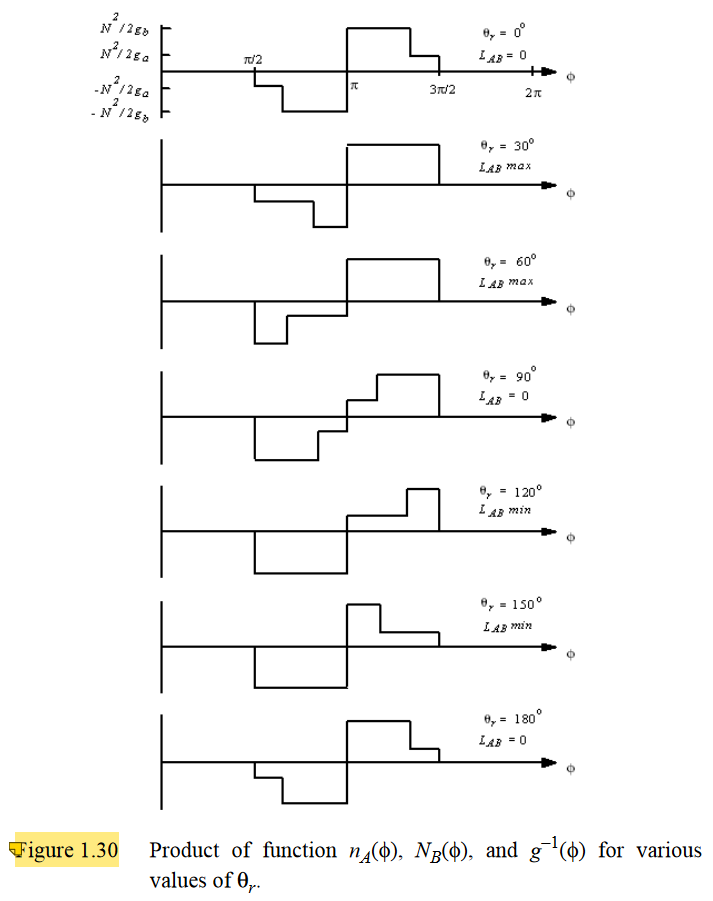

## Problem 3 

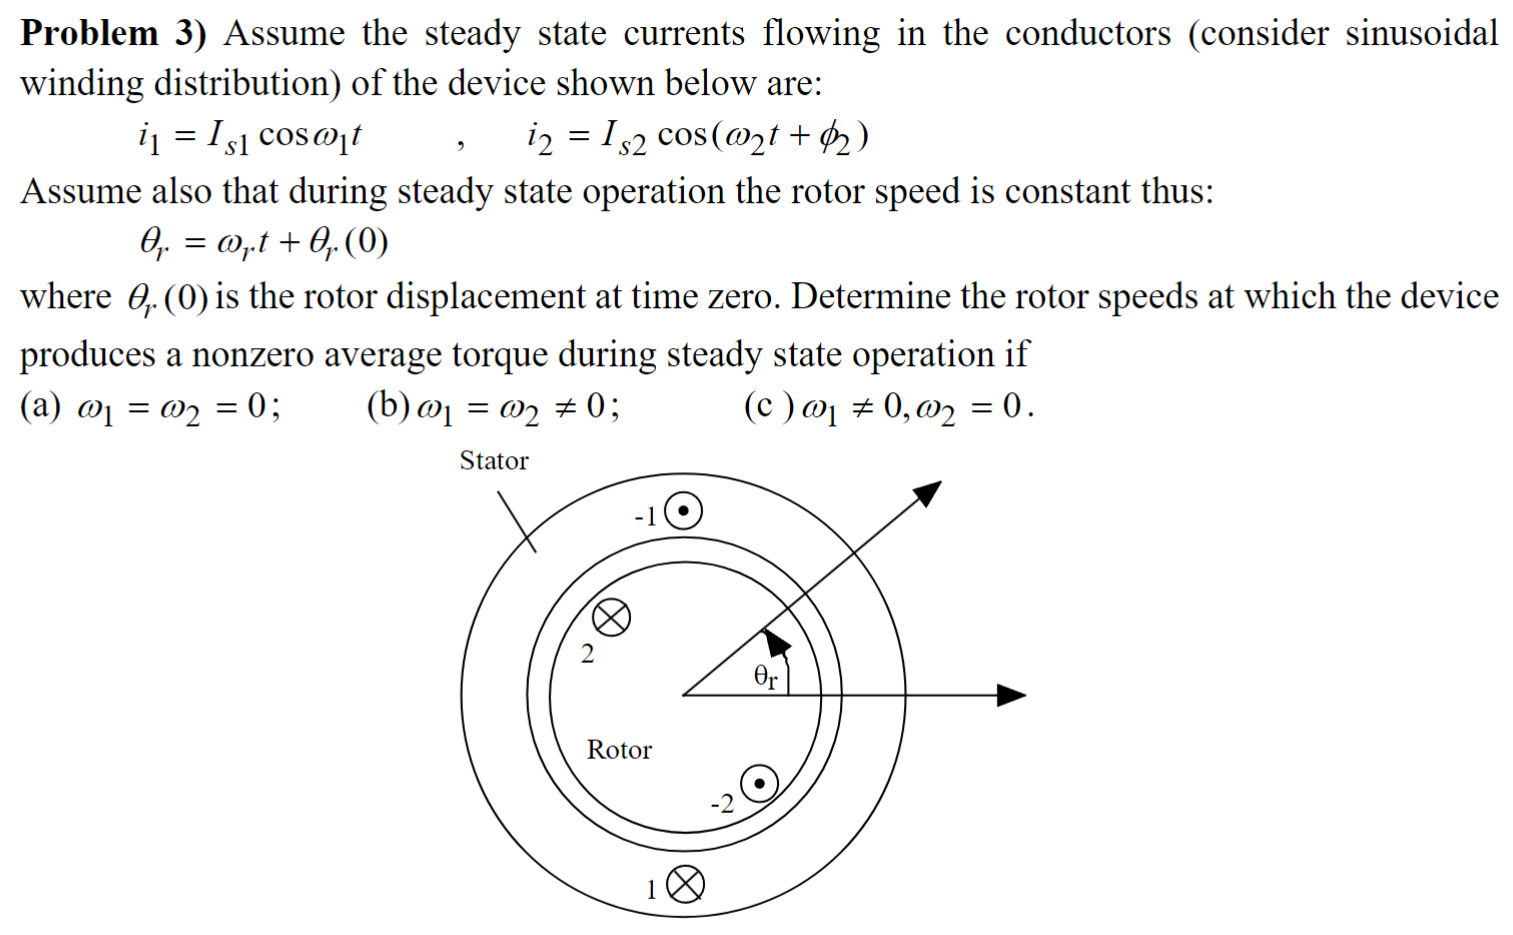

## Appendix 

Square Waveform - Sin 

% syms theta n real
% % syms f(theta) % Define the function symbolically
% 
% % Define the square wave as a piecewise function
% % f(theta) = piecewise(0 <= theta < pi, 1, pi <= theta < 2*pi, 0);
% f_theta = piecewise(0 <= theta < pi, 1, pi <= theta < 2*pi, 0);
% 
% % Define the period
% T = 2*pi;
% 
% % Calculate a0 (DC component)
% a0 = (1/T) * int(f_theta, theta, 0, T);
% 
% % Calculate an (cosine coefficients)
% an = (2/T) * int(f_theta * cos(n * theta), theta, 0, T);
% 
% % Calculate bn (sine coefficients)
% bn = (2/T) * int(f_theta * sin(n * theta), theta, 0, T);
% 
% % Simplify the results
% a0_simplified = simplify(a0);
% an_simplified = simplify(an);
% bn_simplified = simplify(bn);
% 
% digits(4)
% a0 = vpa(a0_simplified)
% an_7 = subs(an_simplified, n, 1:7)
% bn_7 = vpa( subs(bn_simplified, n, 1:7) )
% orderOfHarmonics = 1:7;
% f_theta_fourier = a0 + ...
%                   sum( an_7 .* cos(orderOfHarmonics .* theta) + ...
%                        bn_7 .* sin(orderOfHarmonics .* theta) )
% 
% % Display the coefficients
% % fprintf('a0 = %s\n', char(a0_simplified));
% % fprintf('an = %s\n', char(an_simplified));
% % fprintf('bn = %s\n', char(bn_simplified));
% fplot(f_theta, [0 2*pi])
% hold on 
% fplot(f_theta_fourier, [0 2*pi])
% hold off 
% title('Fourier Series of Square Wave')
% xlabel('\theta')
% ylabel('f(\theta)')
% grid on

Square Waveform - Cos 

% syms theta n real
% % syms f(theta) % Define the function symbolically
% 
% % Define the square wave as a piecewise function
% % f(theta) = piecewise(0 <= theta < pi, 1, pi <= theta < 2*pi, 0);
% f_theta = piecewise(0 <= theta < pi/2, 1, ...
%                     pi/2 <= theta < 3*pi/2, 0, ...
%                     3*pi/2 <= theta < 2*pi, 1);
% 
% % Define the period
% T = 2*pi;
% 
% % Calculate a0 (DC component)
% a0 = (1/T) * int(f_theta, theta, 0, T);
% 
% % Calculate an (cosine coefficients)
% an = (2/T) * int(f_theta * cos(n * theta), theta, 0, T);
% 
% % Calculate bn (sine coefficients)
% bn = (2/T) * int(f_theta * sin(n * theta), theta, 0, T);
% 
% % Simplify the results
% a0_simplified = simplify(a0);
% an_simplified = simplify(an);
% bn_simplified = simplify(bn);
% 
% digits(4)
% a0 = vpa(a0_simplified)
% an_7 = vpa( subs(an_simplified, n, 1:7) )       % even harmonics
% bn_7 = vpa( subs(bn_simplified, n, 1:7) ) % odd harmonics
% orderOfHarmonics = 1:7;
% f_theta_fourier = a0 + ...
%                   sum( an_7 .* cos(orderOfHarmonics .* theta) + ...
%                        bn_7 .* sin(orderOfHarmonics .* theta) )
% 
% % Display the coefficients
% % fprintf('a0 = %s\n', char(a0_simplified));
% % fprintf('an = %s\n', char(an_simplified));
% % fprintf('bn = %s\n', char(bn_simplified));
% fplot(f_theta, [0 2*pi])
% hold on 
% fplot(f_theta_fourier, [0 2*pi])
% hold off 
% title('Fourier Series of Square Wave')
% xlabel('\theta')
% ylabel('f(\theta)')
% grid on
% 
% figure 
% fplot(subs(g_phi_ext_even_inv, vars, [pi/3 0.5 0.8]), [0 T], ...
%     "DisplayName", "Original")
% hold on 
% fplot(subs(g_phi_inv_fourier, vars, [pi/3 0.5 0.8]), [0 T], ...
%     "DisplayName", "Fourier Series")
% % fplot(subs(g_phi_inv_fourier_multi_3_removed, vars, [pi/3 0.5 0.8]), [0 T], ...
% %     "DisplayName", "Fourier Series")
% hold off 
% ylim([0 3])
% grid on 
% legend 